close all
clear
clc

## Software compatibility

Please make sure you have the following installed. You can check this by typing "ver" into the command window 1) Control System Toolbox 2) System Identification Toolbox installed. 

% Also make sure you have Simulink installed. You can check by typing
% "simulink" into the command window.

% This project was compiled on Matlab 2020b. If you have compatibility
% issues, we have also included a 2019a version.

## Part 1: Transfer Function Identification

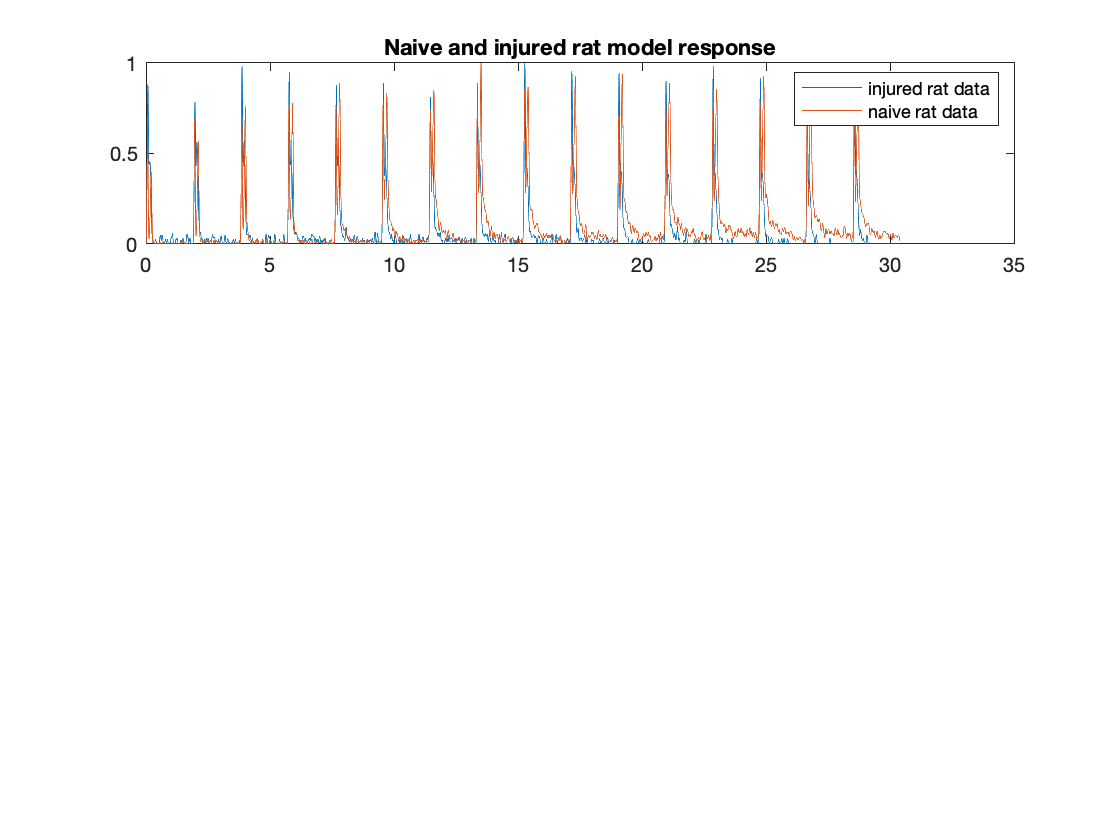

%%%%%%%%%%%%%%%%%%  DO NOT CHANGE!!!! %%%%%%%%%%%%%%%%%%%%%%%
% Set up tranfer function estimation to enforce stability
mdl= @(num_poles,num_zeros) [idtf(NaN(1,1+num_zeros),[1,NaN(1,num_poles)])];
opt = tfestOptions('Display','off','InitMethod','all','InitialCondition','zero','EnforceStability',true) ;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Load in dataset
    % Fs = sampling time (seconds)
    % t = time vector (seconds)
    % r = input (mA)
    % y_i = injured rat WDR response
    % y_n = naive rat WDR response
  
% TO DO: Change the number to reflect your team number.
load('DATASET_2.mat')

% Convert data into the correct format for transfer function estimation
data_n =  iddata(y_n,r,Fs) ; % naive rat
data_i =  iddata(y_i,r,Fs) ; % injured rat

% TO DO: Use the following code to fit your naive rat model, we suggest by
%%% Use find_part1_parameter to compute optimal set of parameters
%%% Naive TF:  num_poles = 9, num_zeros = 9
%%% Injured TF:  num_poles = 9, num_zeros = 5

% Estimate naive TF
init_sys_n = mdl(9, 9) ; 
SYS_N = tfest(data_n,init_sys_n,opt) ;

% Estimate naive WDR response
y_n_est = lsim(SYS_N,r,t) ;

% TO DO: Repeat for injured rat model
% Estimate injured TF
init_sys_i = mdl(9,5) ; 
SYS_I = tfest(data_i,init_sys_n,opt) ;
% Estimate injured WDR response
y_i_est = lsim(SYS_I,r,t) ;

% TO DO: Create plots showing just data
subplot(3,1,1);
plot(t,y_i);
title("Naive and injured rat model response")
hold on
plot(t,y_n);
legend('injured rat data','naive rat data')
hold off

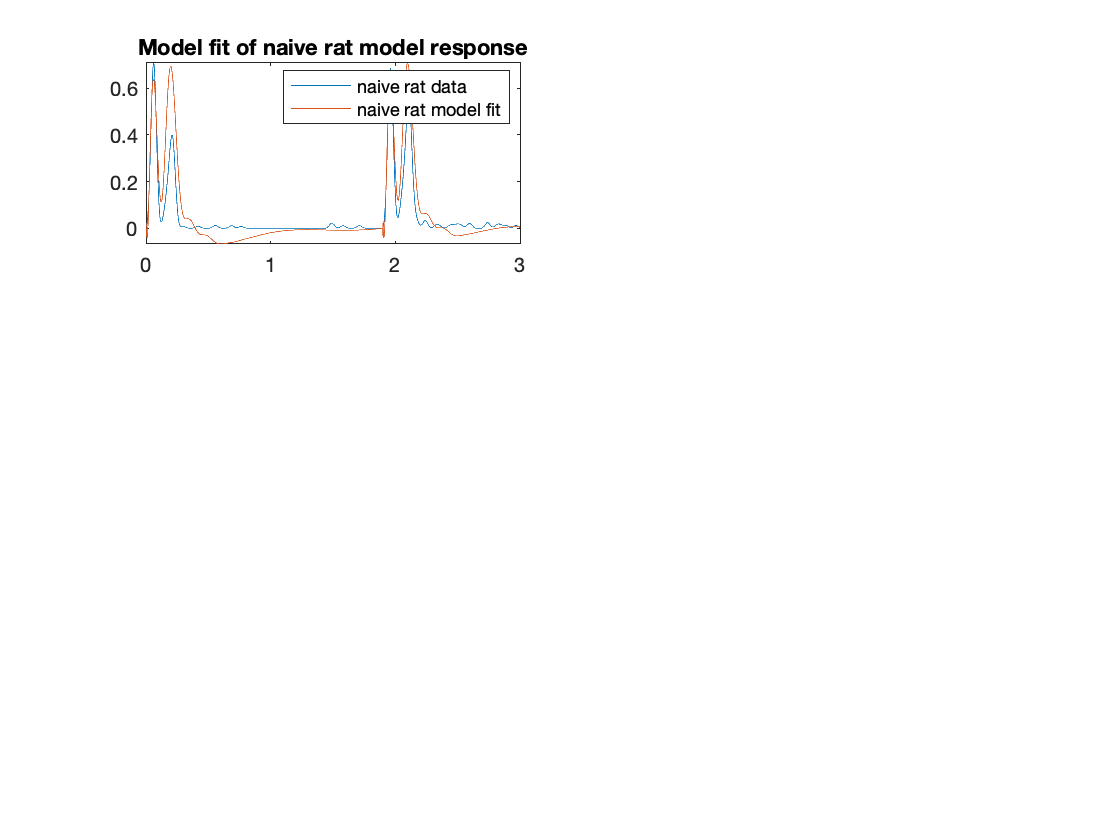


% TO DO: Create plots showing model fits to data
%show naive model fit
subplot(3,2,1);
plot(t,y_n);
title("Model fit of naive rat model response")
hold on
plot(t,y_n_est);
legend('naive rat data','naive rat model fit')
xlim([0,3])
hold off

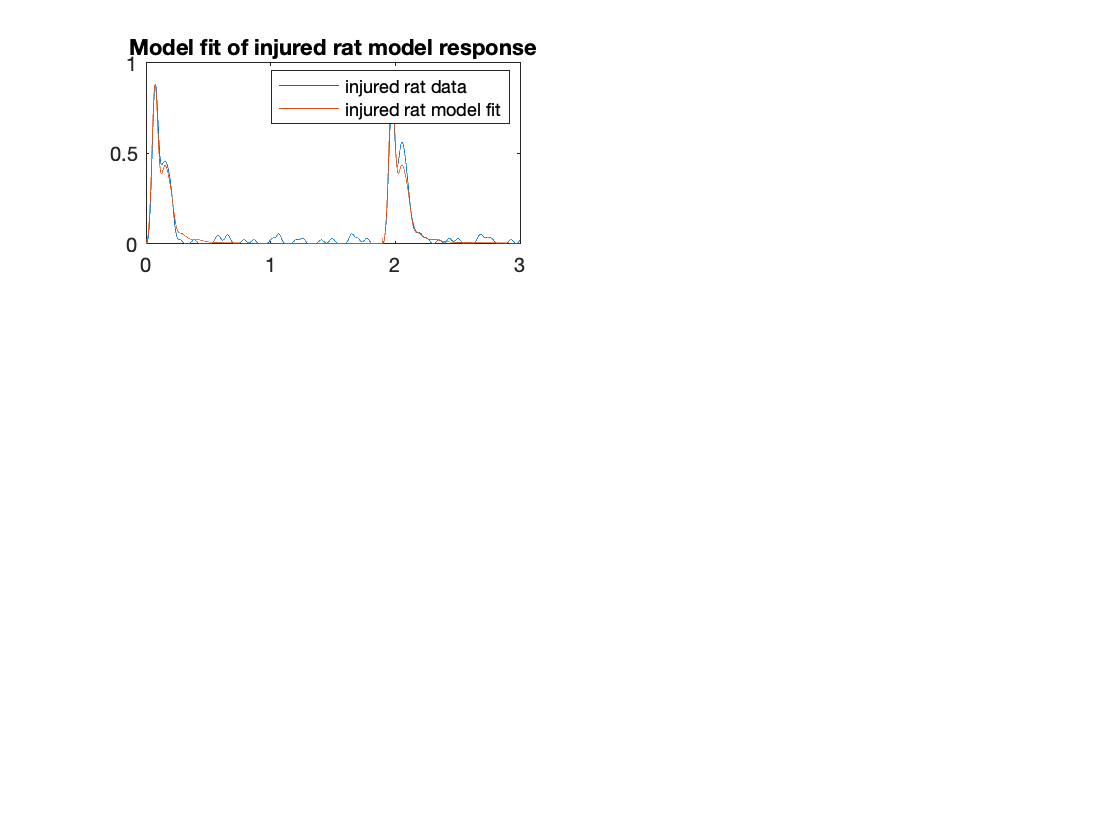


%show injured model fit
subplot(3,3,1);
plot(t,y_i);
title("Model fit of injured rat model response")
hold on
plot(t,y_i_est);
legend('injured rat data','injured rat model fit')
xlim([0,3])
hold off

## Part 2: Control Design

TO DO: Input your final Naive Model and Injured Model from Part 1.

H_N = SYS_N;
H_I = SYS_I;

% Opens the Simulink Model
open('PID_Controller.slx')

% TO DO: double check the simulation parameters (fixed-step integrator)
% 1) Go to the modeling tab, 
% 2) Click on Model Settings
% 3) Under solver selection time select fixed-step, Solver = ode4
% 4) Under solver details set the step size equal to 1e-3
% 5) Ok

% TO DO: Modify parameters of Controller
% You can change the Kp,Ki,Kd parameters here, or you can modify them
% directly in Simulink by changing the values in the PID block

%%% Use find_part2_parameter to compute optimal Kp, Ki, Kd
Kp = 0.0222;
Ki = 0.3171; 
Kd = 0.0003885;

Data = sim('PID_Controller.slx'); % runs the simulink model from here

% Extract responses from Data
time = Data.simout.time;
naive_model_response = Data.simout.signals.values(:,1);
injured_model_response = Data.simout.signals.values(:,2);
closed_loop_injured_model_response = Data.simout.signals.values(:,3);

% TO DO: Create plots showing how well your controller performs
plot(time,naive_model_response);
title("PI control model of injured rat model")
hold on
plot(time,injured_model_response);
plot(time,closed_loop_injured_model_response);
legend('naive rat data','injured rat data','PI control model of injured rat')
hold off

% find the percentage of improvement in close loop control system
% define percentage of improvement = 1 - MSE between naive and injured model / MSE between naive and closed loop model
MSE_NI = mean((naive_model_response - injured_model_response).^2);
MSE_NC = mean((naive_model_response - closed_loop_injured_model_response).^2);
per_improvement = 1 -  MSE_NC / MSE_NI;
disp(per_improvement)

## Closed-loop system to submit to your TA

% TO DO: Define Final Gains - don't change the name, just the value
Kp_final = 0.0222; 
Ki_final = 0.3171; 
Kd_final = 0.0003885;

% TO DO: Change the number in your team name
save('Team_2_Results.mat','Kp_final','Ki_final','Kd_final','H_N','H_I')